clearvars;clc;

data_folder = '.\data\';
patient = 'ai8_micontinuous\';
files{1} = 'ai8.20180320.112744.offline.mi.mi_bhbf.gdf';
files{2} = 'ai8.20180320.113734.offline.mi.mi_bhbf.gdf';
files{3} = 'ai8.20180320.114543.offline.mi.mi_bhbf.gdf';
files{4} = 'ai8.20180320.120206.online.mi.mi_bhbf.ema.gdf';
files{5} = 'ai8.20180320.122511.online.mi.mi_bhbf.dynamic.gdf';
files{6} = 'ai8.20180427.152806.online.mi.mi_bhbf.ema.gdf';
files{7} = 'ai8.20180427.154229.online.mi.mi_bhbf.dynamic.gdf';
files{8} = 'ai8.20180601.153831.online.mi.mi_bhbf.ema.gdf';
files{9} = 'ai8.20180601.154427.online.mi.mi_bhbf.dynamic.gdf';
%mnemonic codes
code.fixation = 786;
code.cue_BH = 773;
code.cue_BF = 771;
code.cue_rest = 783;
code.feedback = 781;
modality.offline = 0;
modality.online = 1;
data_path = './data/';
%sub-band of frequencies of psd we are interested in
selected_frequences = (4:2:48)';
channel_labels  = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4', 'C3', 'C1', 'Cz', 'C2', 'C4', 'CP3', 'CP1', 'CPz', 'CP2', 'CP4'};
num_features = 9;
%load the weigths to select the features
feature_weights = load('features_filter.mat').features_filter';


## load EEG

EEG_data = cell(size(files));

for file = 1 : length(files)
    [s,h] = sload(fullfile(data_path, patient, files{file}));
    EEG_data{file}.signal = s;
    EEG_data{file}.header = h;
end


## convert EEG into PSD

PSD_data = cell(size(EEG_data));
original_frequences=nan;
for eeg_i = 1 : length(EEG_data)
    signal = EEG_data{eeg_i}.signal;
    header = EEG_data{eeg_i}.header;
    PSD_data{eeg_i} = psd_extraction(signal, header);
    %adding modality info
    if contains(files{eeg_i},"offline")
        PSD_data{eeg_i}.modality = modality.offline;
    elseif contains(files{eeg_i},"online")
        PSD_data{eeg_i}.modality = modality.online;
    else
        error(['Unknown modality for file: ' eeg_i]);
    end
    original_frequences = PSD_data{eeg_i}.frequences;
end

[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events
[proc] |- Applying CAR and Laplacian
[proc] |- Computing spectrogram
[proc] |- Extract and convert the events


## concatenate files and label data

[PSD, EVENT, run_labels, modality_labels] = concatenatePSD(PSD_data);

num_windows  = size(PSD, 1);
[cue_type_labels, trial_labels] = labelData(EVENT, num_windows);

offline_data_index = (modality_labels == modality.offline);
online_data_index = (modality_labels == modality.online);
bf_bh_data_index = (cue_type_labels == code.cue_BH | cue_type_labels == code.cue_BF);


## log and sub-frequences extraction

PSD = log(PSD);
[PSD, frequences] = extractFrequences(PSD, original_frequences, selected_frequences);
    

## convert PSDs into dataset for the classifiers


classes = unique(cue_type_labels(bf_bh_data_index));
[X, selected_freq_chan_index , fisher_score_run] = psd2features(PSD, run_labels, cue_type_labels, classes, num_features ,feature_weights);

## compute mean fisher's score

mean_fisher_score = mean(fisher_score_run,3);

## filter mean fisher's score

filtered_mean_Fisher = mean_fisher_score .* feature_weights;

## generate map of selected features

features_mask = zeros(size(mean_fisher_score));

for k = 1 : length(selected_freq_chan_index)
    feature_index = selected_freq_chan_index{k};
    features_mask(feature_index(1), feature_index(2)) = 1;
end

## Visualization Fisher score

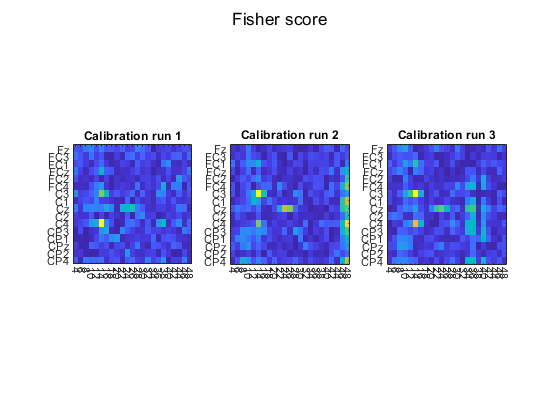

channelId  = 1:length(channel_labels);

NumRuns = length(EEG_data);
NumFreqs = length(frequences);
NumChans = length(channel_labels);
classId    = [773 771];
classLb    = {'both hands', 'both feet'};
nclasses   = length(classId);
modalityId = [0 1];
modalityLb = {'offline', 'online'};
OfflineRuns = [1 2 3];
climits = [];
handles = nan(NumRuns, 1);
fig1 = figure;

for rId = 1:length(OfflineRuns)
    subplot(1, 3, rId);
    imagesc(fisher_score_run(:, :, OfflineRuns(rId))');
    axis square;
    set(gca, 'XTick', 1:NumFreqs);
    set(gca, 'XTickLabel', frequences);
    set(gca, 'YTick', 1:NumChans);
    set(gca, 'YTickLabel', channel_labels);
    xtickangle(-90);
    
    title(['Calibration run ' num2str(OfflineRuns(rId))]);
    
    climits = cat(2, climits, get(gca, 'CLim'));
    handles(OfflineRuns(rId)) = gca;
end


sgtitle('Fisher score');

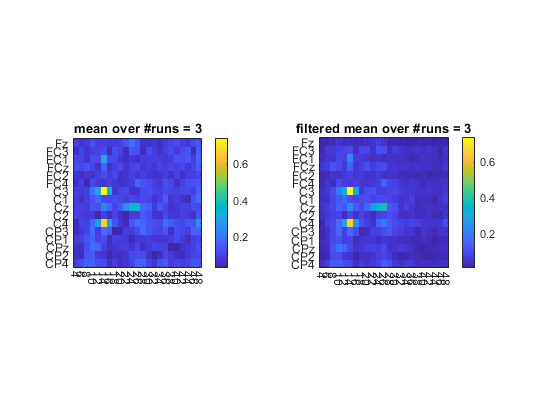

fig2=figure;
subplot(1,2,1);
imagesc(mean_fisher_score');
axis square;
set(gca, 'XTick', 1:NumFreqs);
set(gca, 'XTickLabel', frequences);
set(gca, 'YTick', 1:NumChans);
set(gca, 'YTickLabel', channel_labels);
xtickangle(-90);
colorbar;

title(['mean over #runs = ' num2str(OfflineRuns(rId))]);

subplot(1,2,2);
imagesc(filtered_mean_Fisher');
axis square;
set(gca, 'XTick', 1:NumFreqs);
set(gca, 'XTickLabel', frequences);
set(gca, 'YTick', 1:NumChans);
set(gca, 'YTickLabel', channel_labels);
xtickangle(-90);
colorbar;

title(['filtered mean over #runs = ' num2str(OfflineRuns(rId))]);

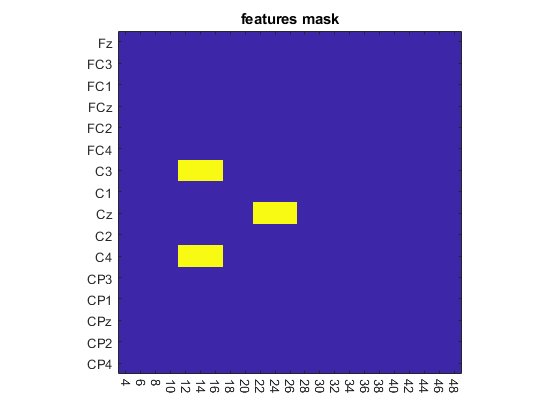



figure3=figure;
imagesc(features_mask');
axis square;
set(gca, 'XTick', 1:NumFreqs);
set(gca, 'XTickLabel', frequences);
set(gca, 'YTick', 1:NumChans);
set(gca, 'YTickLabel', channel_labels);
xtickangle(-90);

title('features mask');

## multi classifier on offline data

sel_bf = {[9 12]};
sel_bh = {[7 6], [11 6]};

data1 = extractFeatures(PSD,sel_bf);
data2 = extractFeatures(PSD,sel_bh);

train_index = (offline_data_index & bf_bh_data_index);
test_index = (online_data_index & bf_bh_data_index);

train_set1 = data1(train_index);
train_set2 = data2(train_index);
label_train = cue_type_labels(train_index);

test_set1 = data1(test_index);
test_set2 = data2(test_index);
label_test = cue_type_labels(test_index);


model1 = fitcdiscr(train_set1,label_train,'DiscrimType','quadratic');
model2 = fitcdiscr(train_set2,label_train,'DiscrimType','quadratic');

## conf matrices

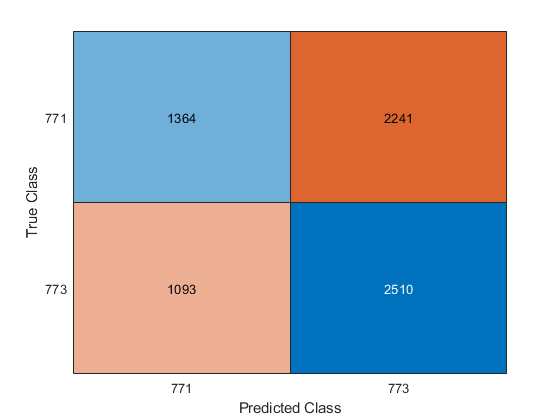

confusionchart(label_train, predict(model1, train_set1));

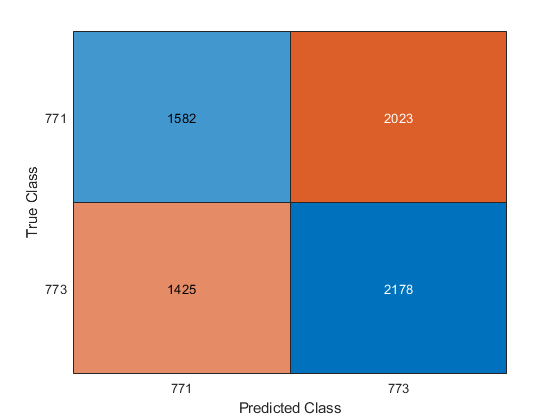

confusionchart(label_train, predict(model2, train_set2));

## train set results

[~, p1] = predict(model1, train_set1);
[~, p2] = predict(model2, train_set2);
p = p1.*p2;
[~, predicted_labels] = max(p,[],2);
predicted_labels = arrayfun(@(x) classes(x), predicted_labels);
accuracy = sum(label_train == predicted_labels)/length(label_train);

disp(["the accuracy on train set is " accuracy]);

    "the accuracy on train set is "    "0.53718"



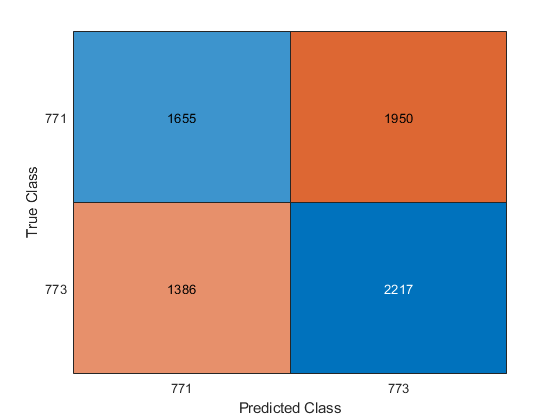

confusionchart(label_train, predicted_labels);

## test the model on online data

[~, p1] = predict(model1, test_set1);
[~, p2] = predict(model2, test_set2);
c1=mean([p1(:,1) p2(:,1)],2);
c2=mean([p1(:,2) p2(:,2)],2);
[~, predicted_labels] = max([c1 c2],[],2);
predicted_labels = arrayfun(@(x) classes(x), predicted_labels);
accuracy = sum(label_test == predicted_labels)/length(label_test);
confusion_matrix = confusionmat(label_test, predicted_labels);

disp(["the accuracy on test set is " accuracy]);

    "the accuracy on test set is "    "0.52375"



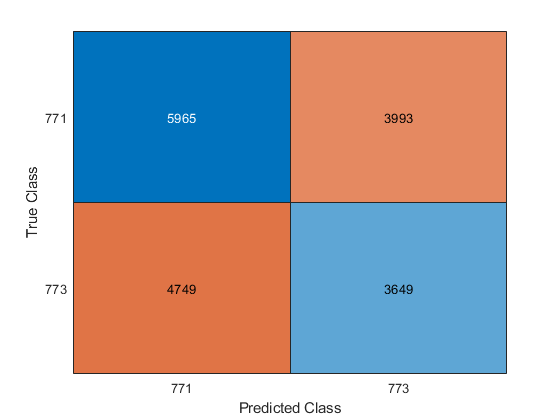

chart=confusionchart(label_test, predicted_labels);